# Google Net Model

## Part A: What is a Google Net Model

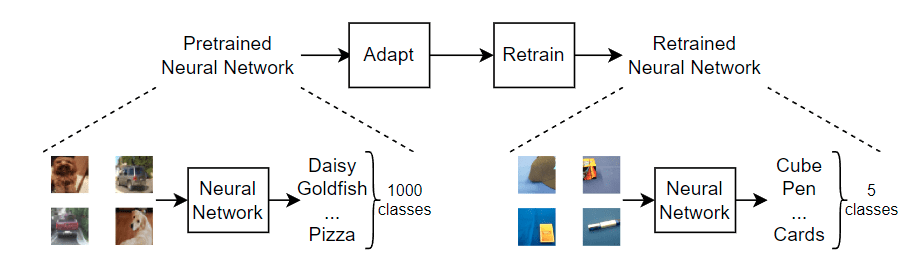

GoogleNet, also known as Inception-v1, is a powerful convolutional neural network (CNN) architecture developed by Google. It's specifically designed to excel in tasks like image classification and object detection. What sets GoogleNet apart is its unique structure, featuring multiple "inception" modules that allow the network to efficiently capture information at different scales and resolutions within an image. These modules employ a combination of parallel convolutional layers with different filter sizes, enabling GoogleNet to learn complex features while keeping computational costs manageable.

In MATLAB, leveraging GoogleNet is straightforward thanks to the Deep Learning Toolbox. With just a few lines of code, beginners can load the pre-trained GoogleNet model and use it to classify images. This pre-trained model comes with learned weights and architecture optimized on massive datasets, making it a great starting point for those new to deep learning. By simply providing an input image, users can quickly obtain predictions, making GoogleNet in MATLAB an accessible tool for image-related tasks even for those without extensive deep learning expertise.

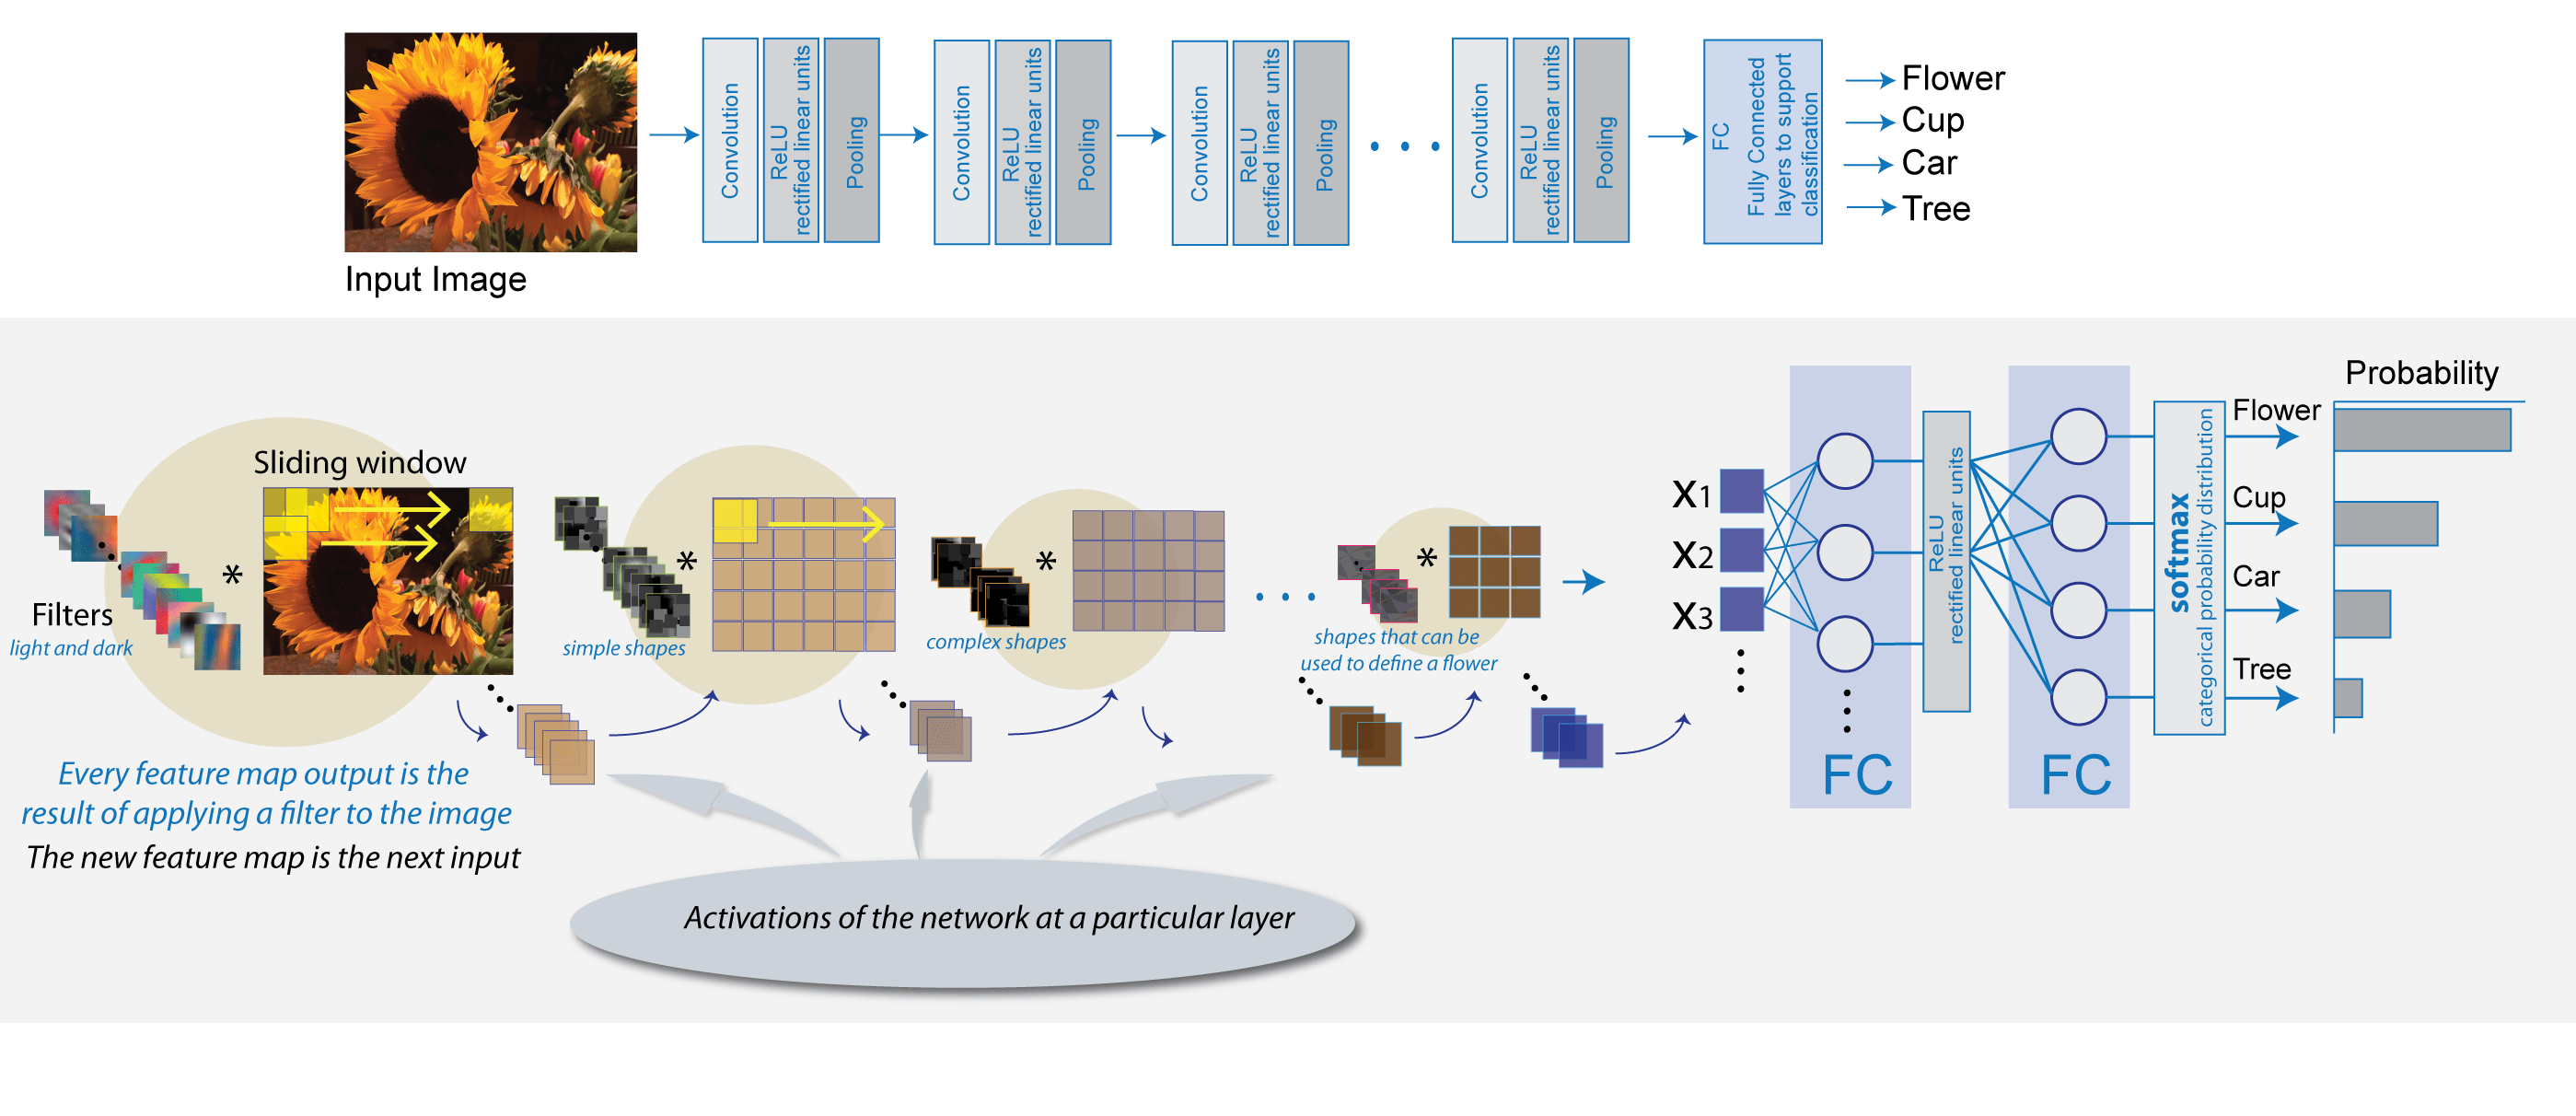

Convolutions in Neural Networks:Convolutions are a fundamental operation in CNNs, designed to process data with a grid-like topology, such as images. A convolution involves sliding a filter (a small matrix) over the input data and performing element-wise multiplication followed by summation. This operation helps in extracting features like edges, textures, and patterns from the input image. Multiple filters can be applied to capture different features, and these filters are learned during the training process.

Why Convolutions are Used:

- Spatial Hierarchies: Convolutions help in detecting hierarchical spatial features in images, starting from low-level features like edges to high-level features like objects.

- Parameter Efficiency: Convolutional layers use fewer parameters compared to fully connected layers, making the network more efficient and less prone to overfitting.

- Translation Invariance: Convolutions help the network to recognize patterns regardless of their position in the image, providing a degree of translation invariance.

Neural networks are computational models inspired by the human brain's structure and function. They consist of layers of interconnected nodes (neurons), where each connection represents a learned weight. Neural networks can learn to perform various tasks by adjusting these weights based on the input data and the desired output.

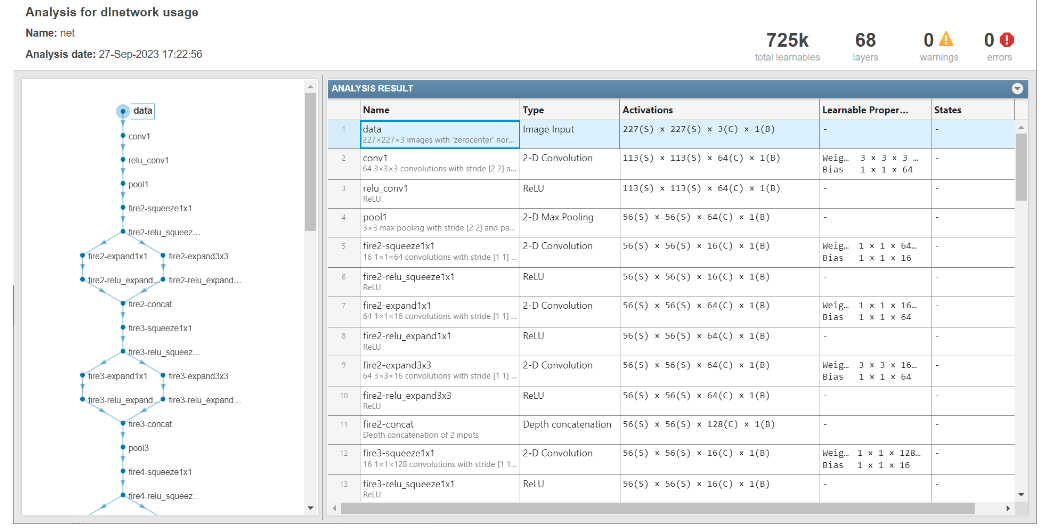

Why Neural Networks are Useful:

- Learning from Data: Neural networks can automatically learn and improve from experience without being explicitly programmed with rules, making them suitable for complex tasks like image recognition, natural language processing, and more.

- Adaptability: They can adapt to different types of data and tasks, thanks to their flexible architecture.

- High Performance: When trained on large datasets, neural networks can achieve state-of-the-art performance in many applications, often surpassing traditional algorithms.

By integrating GoogleNet into MATLAB, users can leverage the power of advanced neural networks for image classification tasks with ease. The combination of MATLAB's user-friendly environment and GoogleNet's robust architecture makes it an excellent tool for both beginners and experienced practitioners in deep learning.

## Part B: Google Net model example

### 1. Data Preparation

clc; clear;
% Load the dataset containing images of faces from a specified folder structure
Dataset = imageDatastore('/MATLAB Drive/MATLAB_Section05_v2/Data/My_Dataset', "IncludeSubfolders", true, "LabelSource", "foldernames");

% Split the dataset into training and validation sets, ensuring a certain number of images per class for validation
[Training_Dataset, Validation_Dataset] = splitEachLabel(Dataset, 7.0);
 

Explanation: Here, we're loading a bunch of images from folders on a computer. Each folder has pictures of a different person's face. Then, we're splitting these pictures into two groups: one group to teach the computer from (training set) and another group to check how well it's learning (validation set).

### 2. Model Selection and Initialization

% Load a pre-trained GoogLeNet model, a deep convolutional neural network renowned for image recognition tasks
numClasses = numel(categories(Dataset.Labels));
net = imagePretrainedNetwork("googlenet", "NumClasses",numClasses); 

% Display the architecture of the GoogLeNet model to understand its structure and layers
analyzeNetwork(net)
 

Explanation: We're using a powerful computer program called GoogLeNet, which is excellent at understanding pictures. But GoogLeNet knows a lot of different things, and right now, it's not specialized to recognize faces. So, we're telling it to prepare itself for our face pictures by adjusting some parts inside it.

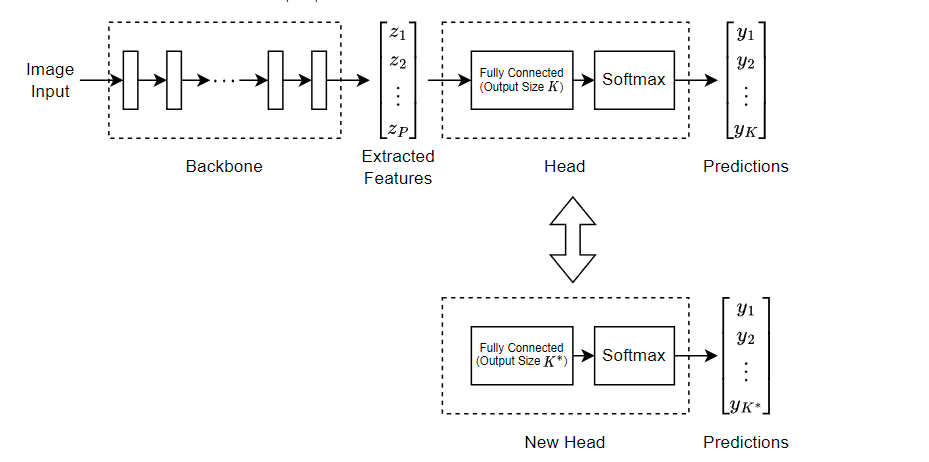

### 3. Data Augmentation

% Define ranges for pixel and scale adjustments to perform data augmentation, enriching the training data
Pixel_Range = [-30 30];
Scale_Range = [0.9 1.1];

% Create an image data augmenter with specified augmentation techniques for robust training
Image_Augmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',Pixel_Range, ...
    'RandYTranslation',Pixel_Range, ...
    'RandXScale', Scale_Range, ...
    'RandYScale', Scale_Range);
 

Explanation: To help the computer learn better from the pictures, we're making some changes to them. We're flipping them horizontally, moving them around a bit, or making them bigger or smaller. These changes help the computer see more variations of the same face, which makes it learn better.

### 4. Creating Augmented Datasets

% Create augmented image datastores for both training and validation datasets using the defined data augmentation techniques
Augmented_Training_Image = augmentedImageDatastore(Input_Layer_size(1:2), Training_Dataset, ...
    'DataAugmentation', Image_Augmenter); 

Unrecognized function or variable 'Input_Layer_Size'.

Augmented_Validation_Image = augmentedImageDatastore(Input_Layer_size(1:2), Validation_Dataset); 
 

Explanation: Now, we're making copies of our pictures, but with those changes we talked about earlier. We'll use these copies to teach the computer and to check how well it's learning. So, if we had 1 picture of someone before, now we might have a few more, each slightly different.

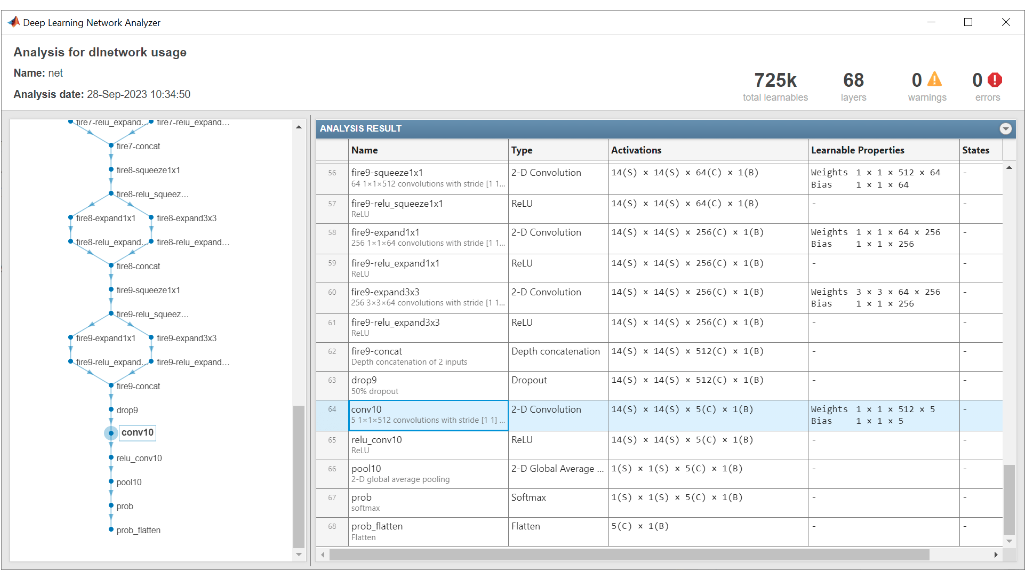

### 5. Training Configuration

% Define parameters for training, such as minibatch size, validation frequency, and training options
Size_of_Minibatch = 5;
Validation_Frequency = floor(numel(Augmented_Training_Image.Files)/Size_of_Minibatch);

% Specify training options including optimizer, learning rate, etc. for model training
Training_Options = trainingOptions('sgdm', ...
    'MiniBatchSize',Size_of_Minibatch, ...
    'MaxEpochs', 6, ...
    'InitialLearnRate', 3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData', Augmented_Validation_Image, ...
    'ValidationFrequency', Validation_Frequency, ...
    'Verbose',false, ...
    'Plot','training-progress');
 

Explanation: We're setting some rules for teaching the computer. We're deciding how many pictures to show it at once, how many times to teach it, and how quickly to teach it. We're also deciding when to check how well it's learning.

### 6. Training

% Train the modified GoogLeNet model using augmented training data and specified training options
net = trainnet(Augmented_Training_Image, net, "crossentropy", Training_Options);
 

Explanation: Finally, we're starting the teaching process. We're showing the computer our pictures with the changes we made earlier, and we're following the rules we set before. The computer is learning from these pictures, getting better each time. We're using a special method called cross-entropy to measure how well it's learning.

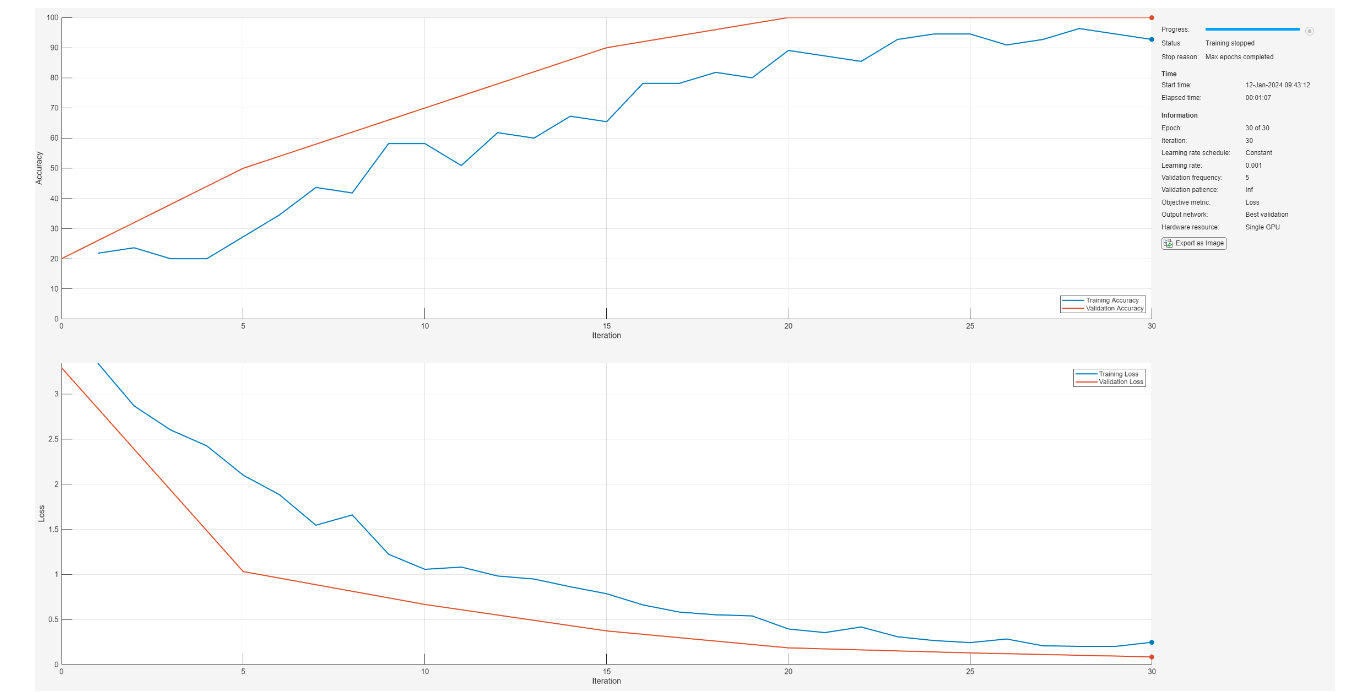

This specific neural network is designed for image identification of three celebrities: Bruno Mars, Elon Musk, and Selena Gomez. To test this program, download the image identification test function from canvas and test the following images: image1.jpg, image2.jpg, and image3.png.

%save the folder name as a variable for readability
folder_name = '/MATLAB Drive/MATLAB - Section 05 ( Teacher - File Share)/Data/My_Dataset'
% Load the dataset containing images of faces from the specified folder structure
Dataset = imageDatastore(folder_name, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Split the dataset into training and validation sets, ensuring 7 images per class for validation
[Training_Dataset, Validation_Dataset] = splitEachLabel(Dataset, 7.0);

% Load the pre-trained GoogLeNet model, a deep convolutional neural network renowned for image recognition tasks
net = googlenet; 

% Display the architecture of the GoogLeNet model to understand its structure and layers
analyzeNetwork(net);

% Obtain the input size of the first layer of the GoogLeNet model
Input_Layer_size = net.Layers(1).InputSize;

% Create a layer graph to visualize and modify the network architecture
Layer_graph = layerGraph(net);

% Extract the feature learner and output classifier layers from GoogLeNet
Feature_Learner = net.Layers(142);
Output_Classifer = net.Layers(144);

% Determine the number of classes in the training dataset for configuring the final layers
Number_of_classes = numel(categories(Training_Dataset.Labels));

% Define a new fully connected layer to adapt the model to the specific classification task
New_Feature_Learner = fullyConnectedLayer(Number_of_classes, ...
    'Name', 'Facial Feature Learner', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);

% Define a new classification layer to match the number of classes in the dataset
New_Classifier_Layer = classificationLayer('Name', 'Face Classifier');

% Replace the original feature learner and output classifier layers in the network graph with the new ones
Layer_graph = replaceLayer(Layer_graph, Feature_Learner.Name, New_Feature_Learner);
Layer_graph = replaceLayer(Layer_graph, Output_Classifer.Name, New_Classifier_Layer); 

% Visualize the modified network architecture after layer replacement
analyzeNetwork(Layer_graph)

% Define ranges for pixel and scale adjustments for data augmentation to enrich training data
Pixel_Range = [-30 30];
Scale_Range = [0.9 1.1];

% Create an image data augmenter with specified augmentation techniques for robust training
Image_Augmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',Pixel_Range, ...
    'RandYTranslation',Pixel_Range, ...
    'RandXScale', Scale_Range, ...
    'RandYScale', Scale_Range);

% Create augmented image datastores for both training and validation datasets with data augmentation
Augmented_Training_Image = augmentedImageDatastore(Input_Layer_size(1:2), Training_Dataset, ...
    'DataAugmentation', Image_Augmenter); 
Augmented_Validation_Image = augmentedImageDatastore(Input_Layer_size(1:2), Validation_Dataset); 

% Define minibatch size and validation frequency for training options
Size_of_Minibatch = 5;
Validation_Frequency = floor(numel(Augmented_Training_Image.Files)/Size_of_Minibatch);

% Specify training options including optimizer, learning rate, etc. for model training
Training_Options = trainingOptions('sgdm', ...
    'MiniBatchSize',Size_of_Minibatch, ...
    'MaxEpochs', 6, ...
    'InitialLearnRate', 3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData', Augmented_Validation_Image, ...
    'ValidationFrequency', Validation_Frequency, ...
    'Verbose',false, ...
    'Plot','training-progress');

% Train the modified GoogLeNet model using augmented training data and specified training options
net = trainNetwork(Augmented_Training_Image, Layer_graph, Training_Options);
 